PID Evaluation

coilsParameters
%%%X-axis
x.C = pid(x.PID.Ki,x.PID.Kd,x.PID.Kp);
x.tF = tf([x.Tz 1]*x.Kp,[( x.Tp1*x.Tp2) (x.Tp1+x.Tp2) 1]);
[x.C_pi,info] = pidtune(x.tF,'PID',0.03)

x = struct with fields:
      Kp: 3.6392e+03
     Tp1: 108.6500
     Tp2: 0.5243
      Tz: 24.1990
     PID: [1×1 struct]
       C: [1×1 pid]
      tF: [1×1 tf]
     sys: [1×1 tf]
    C_pi: [1×1 pid]


info = struct with fields:
                Stable: 1
    CrossoverFrequency: 0.0300
           PhaseMargin: 69.1961


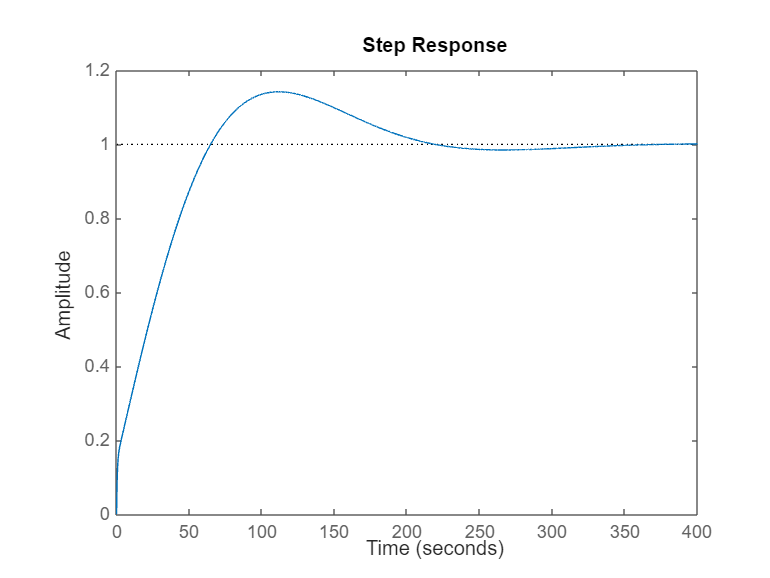

x.sys = feedback(x.C_pi*x.tF,1);
figure()
step(x.sys);

stepinfo(x.sys)

ans = struct with fields:
         RiseTime: 52.1638
    TransientTime: 198.8810
     SettlingTime: 198.8810
      SettlingMin: 0.9002
      SettlingMax: 1.1423
        Overshoot: 14.2311
       Undershoot: 0
             Peak: 1.1423
         PeakTime: 111.5368



%%Y-axis
y.C = pid(y.PID.Ki,y.PID.Kd,y.PID.Kp);
y.tF = tf([y.Tz 1]*y.Kp,[(y.Tp1*y.Tp2) (y.Tp1+y.Tp2) 1]);
[y.C_pi,info] = pidtune(y.tF,'PID',0.03)

y = struct with fields:
      Kp: 6.9007e+03
     Tp1: 4.5513
     Tp2: 4.3827
      Tz: 2.7486
     PID: [1×1 struct]
       C: [1×1 pid]
      tF: [1×1 tf]
     sys: [1×1 tf]
    C_pi: [1×1 pid]


info = struct with fields:
                Stable: 1
    CrossoverFrequency: 0.0300
           PhaseMargin: 79.4485


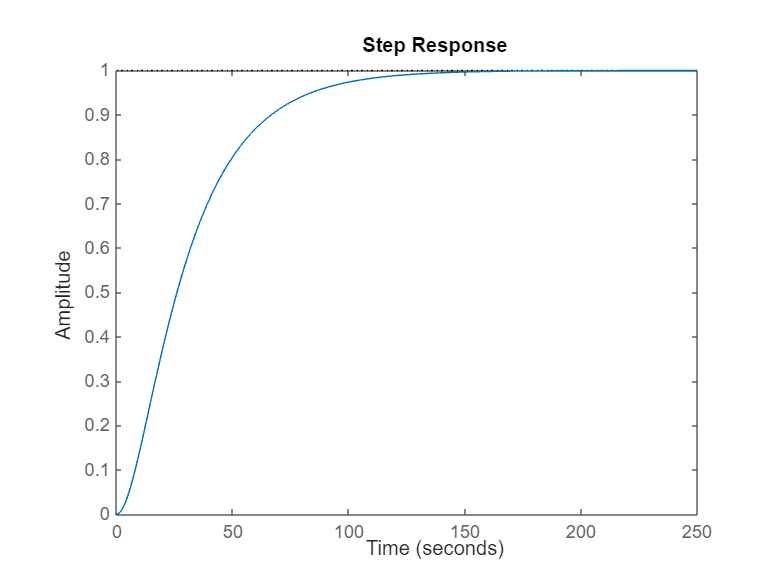

y.sys = feedback(series(y.C_pi,y.tF),1);
figure()
step(y.sys);

stepinfo(y.sys)

ans = struct with fields:
         RiseTime: 58.5966
    TransientTime: 106.6030
     SettlingTime: 106.6030
      SettlingMin: 0.9003
      SettlingMax: 0.9999
        Overshoot: 0
       Undershoot: 0
             Peak: 0.9999
         PeakTime: 242.9771


%z-axis
%%Y-axis
z.C = pid(z.PID.Ki,z.PID.Kd,z.PID.Kp);
z.tF = tf([z.Tz 1]*z.Kp,[(z.Tp1*z.Tp2) (z.Tp1+z.Tp2) 1]);
[z.C_pi,info] = pidtune(z.tF,'PID',0.2)

z = struct with fields:
      Kp: 3.1379e+03
     Tp1: 46.1340
     Tp2: 0.3550
      Tz: 166.0800
     PID: [1×1 struct]
       C: [1×1 pid]
      tF: [1×1 tf]
     sys: [1×1 tf]
    C_pi: [1×1 pid]


info = struct with fields:
                Stable: 1
    CrossoverFrequency: 0.2000
           PhaseMargin: 90.3998


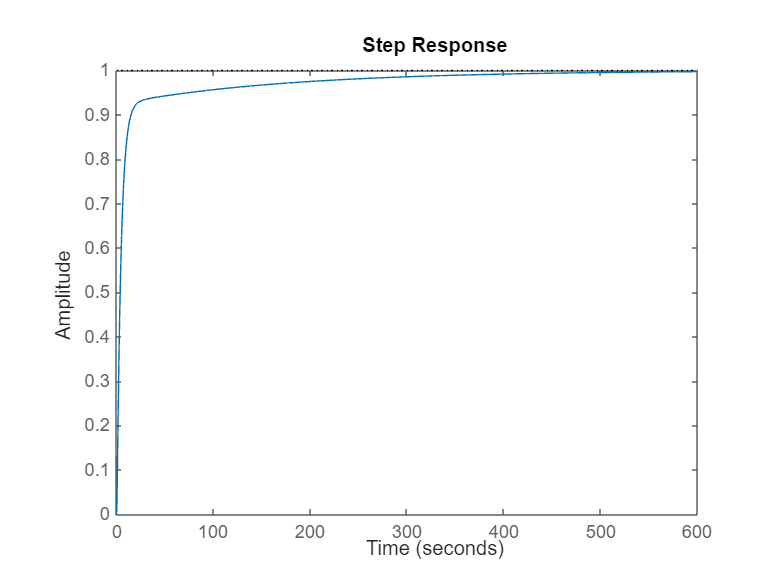

z.sys = feedback(series(z.C_pi,z.tF),1);
figure()
step(z.sys);

stepinfo(z.sys)

ans = struct with fields:
         RiseTime: 14.0537
    TransientTime: 238.8445
     SettlingTime: 238.8445
      SettlingMin: 0.9010
      SettlingMax: 0.9976
        Overshoot: 0
       Undershoot: 0
             Peak: 0.9976
         PeakTime: 616.1879


coilsParameters
salidas=sim('simplePID',['Src' ...
    'Workspace'],'current');

yout = salidas.get('yout');
t    = salidas.get('tout');
%%%Asign measured values
e=yout(:,1:3); u=yout(:,4:6); y=yout(:,7:9); r=yout(:,10:12);

figure()
ax = subplot(2,1,1);
plot(t,y); hold on; grid on;
plot(t,r,'--'); 
xlabel('time(s)'); ylabel('B(nT)');
bx = subplot(2,1,2);
plot(t,u); grid on;
xlabel('time(s)'); ylabel('V');
linkaxes([ax,bx],'x');